# **METODY OPTYMALIZACJI**

### *ĆWICZENIA LABORATORYJNE NR. 8*

# Metoda największego spadku

clearvars all; close all;
syms x1 x2

**Przykład 4.2, 4.4**

% f1 = x1.^2 + x2.^2;
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% eps = 1e-2;
% P = [4, 4];
% h0 = 0.3;
% max_iter = 100;
% 
% [min, iter, x] = const_steepest_descent_method(f, grad, P, h0, eps, max_iter);
% 
% display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)
% display_results(f, min, iter)
% 
% [min, iter, x] = steepest_descent_method(f, grad, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)
% display_results(f, min, iter)

**Przykład 4.3, 4.5**

% f1 = 2.5*(x1.^2 - x2).^2 + (1 - x1).^2;
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% eps = 1e-3;
% P = [-0.5, 1];
% h0 = 0.05;
% max_iter = 200;
% 
% [min, iter, x] = const_steepest_descent_method(f, grad, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-2 2 -1 2], 1)
% display_results(f, min, iter)
% 
% [min, iter, x] = steepest_descent_method(f, grad, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-2 2 -1 2], 1)
% display_results(f, min, iter)

# Metoda Newtona

clearvars all; close all;
syms x1 x2

**Przykład 4.8**

% f1 = 3*x1.^2 + 3*x2.^2 - 4*x1*(1+x2) - x2 + 2;
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% hes1 = hessian(f1);
% hes = inline(hes1);
% 
% eps = 1e-2;
% P = [-4, -4];
% h0 = 0.05;
% max_iter = 100;
% 
% [min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)
% display_results(f, min, iter)

**Przykład 4.9**

% f1 = x1.^2 + x2.^2 - 40/(x1.^2 + x2.^2 + 1);
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% hes1 = hessian(f1);
% hes2 = inline(hes1);
% hes = @(x) hes2(x(1), x(2));
% 
% eps = 1e-2;
% P = [-4, -4];
% h0 = 0.05;
% max_iter = 100;
% 
% [min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)
% display_results(f, min, iter)

**Rysunek 4.19 a)**

% f1 = x1.^2 + x2.^2 - 400/(100*x1.^2 + x2.^2 + 1);
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% hes1 = hessian(f1);
% hes2 = inline(hes1);
% hes = @(x) hes2(x(1), x(2));
% 
% eps = 1e-2;
% P = [0.5, 3];
% h0 = 0.05;
% max_iter = 100;
% 
% [min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-2 2 -1 5], 5)
% display_results(f, min, iter)

**Rysunek 4.19 b)**

% f1 = 2.5*(x1.^2 - x2).^2 + (1 - x1).^2;
% f2 = inline(f1);
% f = @(x) f2(x(1), x(2));
% 
% grad = gradient(f1);
% G = inline(grad);
% grad = @(x) G(x(1), x(2));
% 
% hes1 = hessian(f1);
% hes2 = inline(hes1);
% hes = @(x) hes2(x(1), x(2));
% 
% eps = 1e-2;
% P = [-0.5, 1];
% h0 = 0.05;
% max_iter = 100;
% 
% [min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
% display_method(f1, f, x, [0 0], [-2 2 -2 3], 1)
% display_results(f, min, iter)

# Zadania UPEL

(1) f = @(x1, x2) x1.* exp(-x1.^2 - x2.^2)

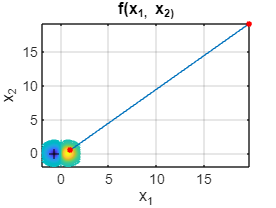

f1 = x1.*exp(-x1.^2 - x2.^2);
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

eps = 1e-6;
P01 = [1, 0.5]; 
P02 = [1.5, -0.5];
h0 = 0.05;
max_iter = 100;
step = 0.01;

[min, iter, x] = steepest_descent_method(f, grad, P01, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-2 2 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 19.776307, 19.276307
Function value at x*: 0.000000



[min, iter, x] = newton_method(f, grad, hes, P01, h0, eps, max_iter);

hesjan


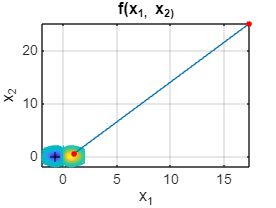

display_method(f1, f, x, [0, 0], [-2 2 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 17.383000, 25.074500
Function value at x*: 0.000000


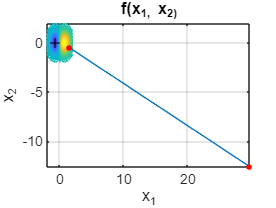


[min, iter, x] = steepest_descent_method(f, grad, P02, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 29.742421, -12.603895
Function value at x*: 0.000000



[min, iter, x] = newton_method(f, grad, hes, P02, h0, eps, max_iter);

hesjan


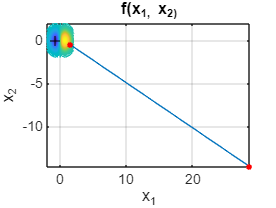

display_method(f1, f, x, [0, 0], [-2 2 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 28.662809, -14.728138
Function value at x*: 0.000000


(2) f = @(x1, x2) 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2)

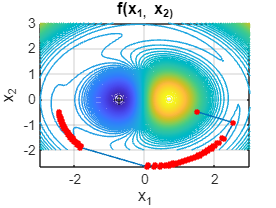

f1 = 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2);
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

eps = 1e-6;
P01 = [1.5, -0.5]; 
P02 = [-1.8, -1.5];
h0 = 0.05;
max_iter = 200;
step = 1;

[min, iter, x] = steepest_descent_method(f, grad, P01, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-3 3 -2 3], step)

display_results(f, min, iter)

Number of iterations: 142
Point x*: -2.453968, -0.502470
Function value at x*: -1.117118


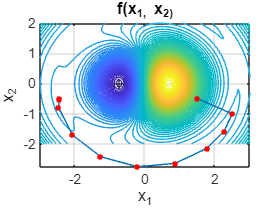


[min, iter, x] = newton_method(f, grad, hes, P01, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-3 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 11
Point x*: -2.453968, -0.502465
Function value at x*: -1.117118


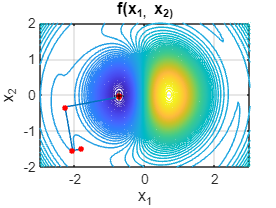


[min, iter, x] = steepest_descent_method(f, grad, P02, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-3 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 8
Point x*: -0.737273, -0.001263
Function value at x*: -32.611160


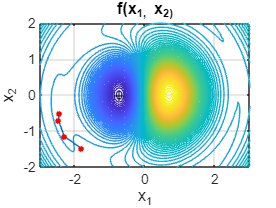


[min, iter, x] = newton_method(f, grad, hes, P02, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-3 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 5
Point x*: -2.453968, -0.502465
Function value at x*: -1.117118


# Zadania problemowe

Które z poniższych funkcji są formą kwadratową?

(1)

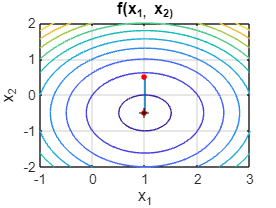

f1 = x1^2 - 2*x1 + x2^2 + x2 + 1;
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes = inline(hes1);

eps = 1e-6;
P = [1, 0.5];
h0 = 0.05;
max_iter = 100;
step = 1;

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-1 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 1.000000, -0.500000
Function value at x*: -0.250000


(2)

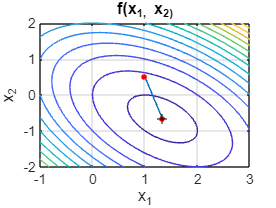

f1 = x1^2-2*x1+x2^2+x1*x2+1;
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes = inline(hes1);

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-1 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 1.333333, -0.666667
Function value at x*: -0.333333


(3)

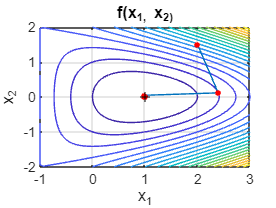

f1 = x1^2-2*x1+x2^2+x1*x2^2+1;
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

P = [2, 1.5];

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-1 3 -2 2], step)

display_results(f, min, iter)

Number of iterations: 4
Point x*: 1.000000, 0.000000
Function value at x*: 0.000000


(4)

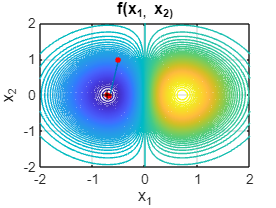

f1 = x1.* exp(-x1.^2 - x2.^2);
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

P = [-0.5, 1];
step = 0.01;

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0, 0], [-2 2 -2 2], step)

display_results(f, min, iter)

Number of iterations: 3
Point x*: -0.707107, -0.000000
Function value at x*: -0.428882


function display_method(f1, f, x, xs, ax, step)
    figure()
    fcontour(f1, ax, 'LevelStep', step); grid on; hold on;
    %title({"f(x_1, x_2) = " + latex(f1)});
    title('f(x_1, x_2)'); xlabel('x_1'); ylabel('x_2'); 
    plot(x(:,1), x(:,2), '-', 'Marker', '.', 'MarkerSize', 10, 'MarkerEdgeColor', 'r')
    f_min = fminsearch(f,xs(1,:));
    plot(f_min(end,1), f_min(end,2), 'k+')
    
    hold off
end

function display_method_2(f1, f, x, xs, ax, step)
    figure()
    fcontour(f1, ax, 'LevelStep', step); grid on; hold on;
    title(latex(f1), 'Interpreter','latex'); xlabel('x_1'); ylabel('x_2'); 
    plot(x(:,1), x(:,2), '-', 'Marker', '.', 'MarkerSize', 10, 'MarkerEdgeColor', 'r')
    f_min = fminsearch(f,xs(1,:));
    plot(f_min(end,1), f_min(end,2), 'k+')
    
    hold off
end

function display_results(f, min, iter)
    fprintf('Number of iterations: %d\n', iter)
    fprintf('Point x*: %f, %f\n', min(:,1), min(:,2))
    fprintf('Function value at x*: %f\n', f(min))
end

function [minimum, iter, matrix]= const_steepest_descent_method(func, grad, x0, h0, epsilon, max_iterations)
    h = h0;
    i = 0;
    matrix = x0;
    while i < max_iterations
        direction = -grad(x0)';
        
        x = x0 + h * direction;
        matrix = [matrix; x];

        if norm(x - x0) < epsilon
            break;
        end
        x0 = x;
        i = i + 1;
    end

    minimum = x;
    iter = i;
end

function [minimum, iter, matrix] = steepest_descent_method(func, grad, x0, h0, epsilon, max_iterations)
    h = h0;
    i = 0;
    matrix = x0;

    while i < max_iterations
        direction = -grad(x0)';
        g  = @(a) func(x0 + a * direction);
        h = fminsearch(g, 0);
        x = x0 + h * direction;
        matrix = [matrix; x];

        if norm(x - x0) < epsilon
            break;
        end
        
        i = i + 1;
        x0 = x;
    end

    minimum = x;
    iter = i;
end

function [minimum, iter, matrix] = newton_method(func, grad, hes, x0, h0, epsilon, max_iterations)
    h = h0;
    i = 0;
    matrix = x0;

    while i < max_iterations
        if cond(hes(x0)) > 1/epsilon
            disp('hesjan')
            break;
        end
        
        if norm(grad(x0)) < 0
            disp('hesjan')
            break;
        end
        
        direction = (-inv(hes(x0)) * grad(x0))';
        g  = @(a) func(x0 + a * direction);
        h = fminsearch(g, 0);
        x = x0 + h * direction;
        matrix = [matrix; x];

        if norm(x - x0) < epsilon
            break;
        end

        i = i + 1;
        x0 = x;
    end

    minimum = x0;
    iter = i;
end